sampling_frequency = 600;
T = 1/sampling_frequency;
orange = "#EDB120";

**Conventional AM**

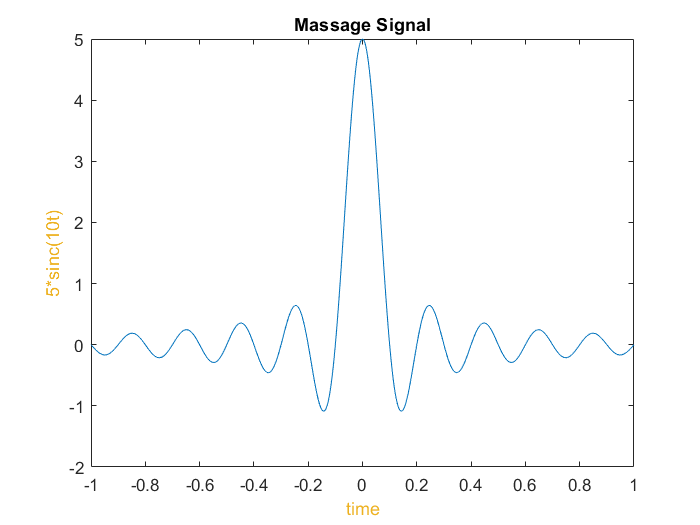

t = -1:T:1;
massage = 5 * sinc(10*t);

figure
plot(t, massage);
xlabel("time", "Color", orange);
ylabel("5*sinc(10t)", "Color", orange);
title("Massage Signal");

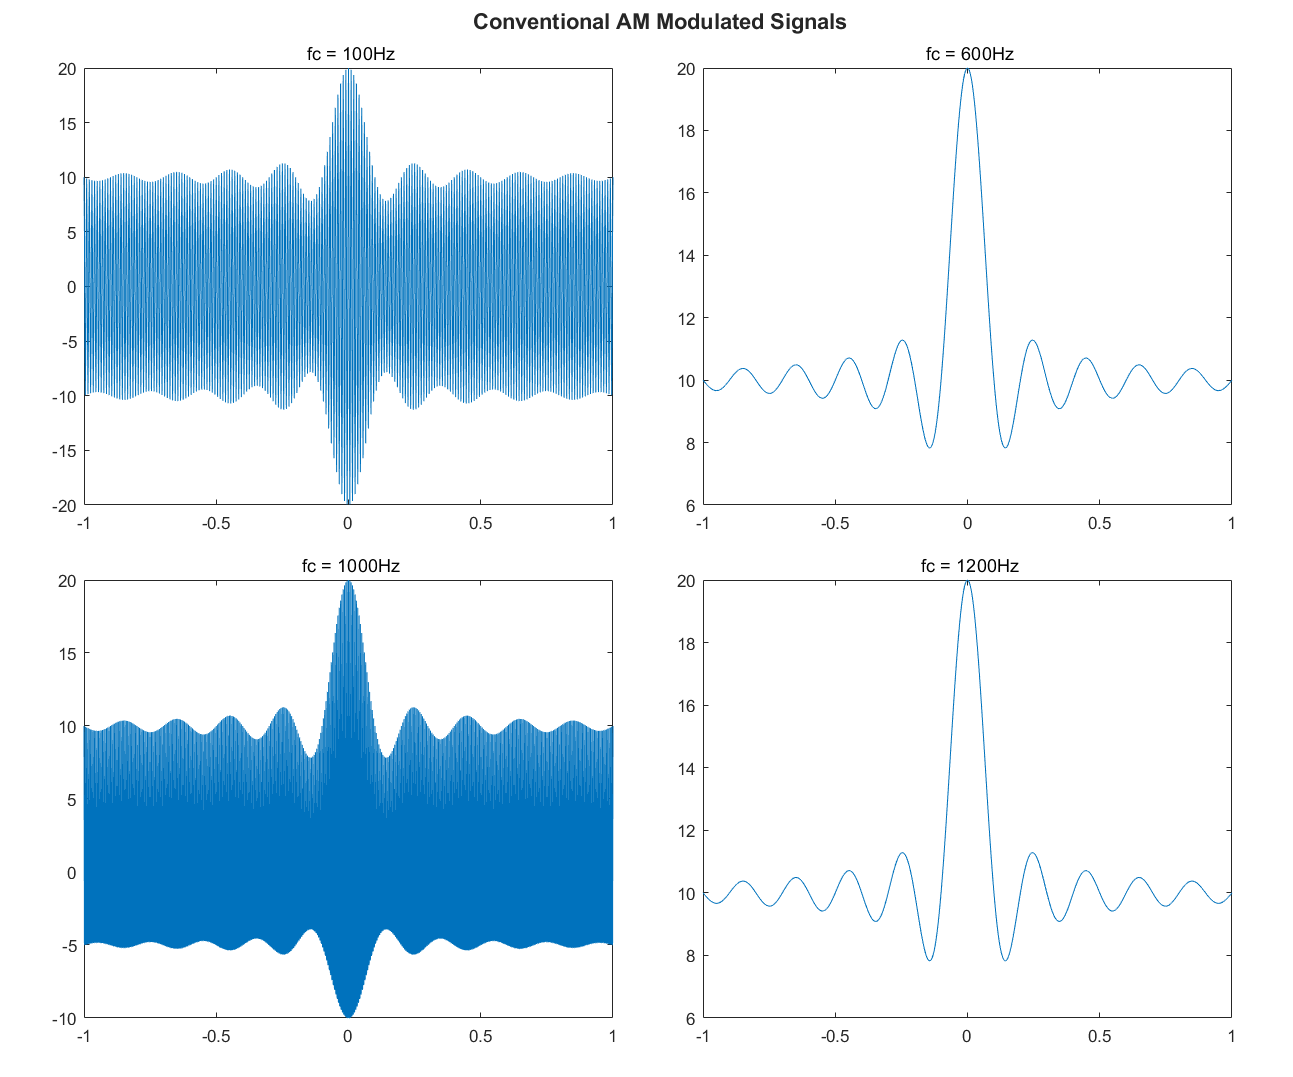

fc = [100, 600, 1000, 1200];
modulated_signals = cell(4, 1);

figure
fig = tiledlayout(2, 2);
fig.Padding = "compact";
fig.TileSpacing = "compact";
set(gcf, "position", [0, 0, 1200, 1000]);
for i = 1:4
    modulated_signals{i} = cAM_modulator(massage, 10, 0.2, fc(i), sampling_frequency);
    nexttile
    plot(t, modulated_signals{i});
    title("\rm fc = " + string(fc(i)) + "Hz");
end
sgtitle("\bf Conventional AM Modulated Signals");

freqs = -sampling_frequency/2 : 0.5 : sampling_frequency/2;
massage_freqs = fftshift(fft(massage)) ./ length(massage);
modulated_100Hz_freqs = fftshift(fft(modulated_signals{1})) ./ length(massage);

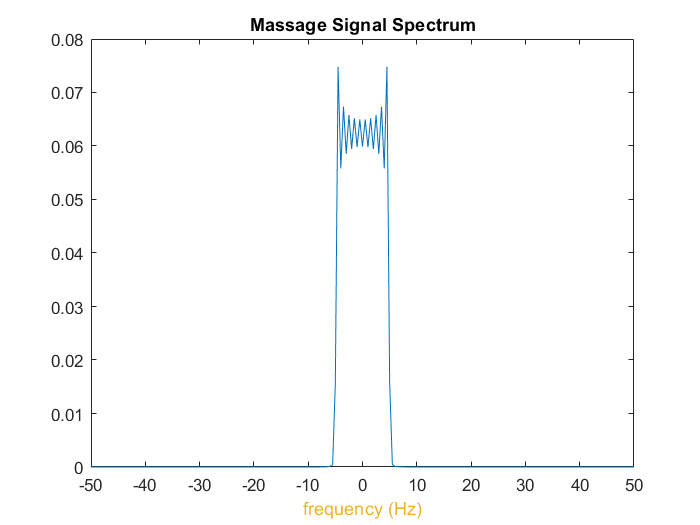

figure
plot(freqs, abs(massage_freqs).^2);
xlim([-50, 50]);
xlabel("frequency (Hz)", "Color", orange);
title("Massage Signal Spectrum");

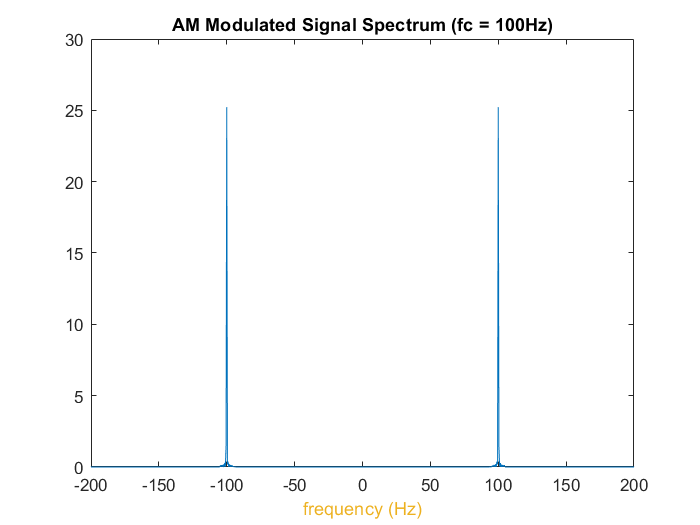

figure
plot(freqs, abs(modulated_100Hz_freqs).^2);
xlim([-200, 200]);
xlabel("frequency (Hz)", "Color", orange);
title("AM Modulated Signal Spectrum (fc = 100Hz)");

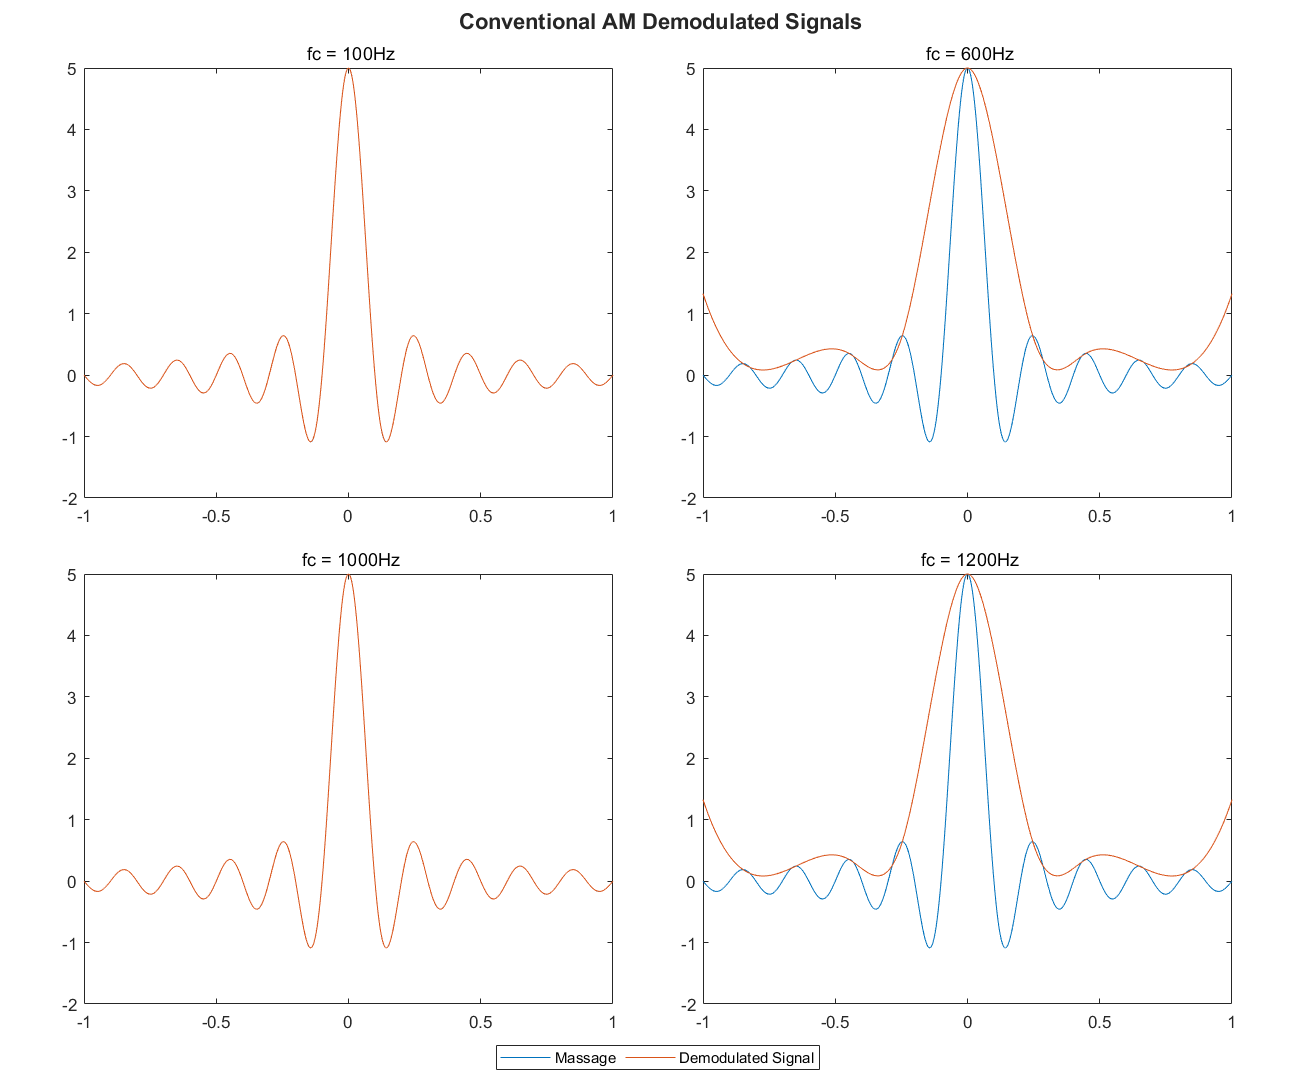

demodulated_signals = cell(4, 1);

figure
fig = tiledlayout(2, 2);
fig.Padding = "compact";
fig.TileSpacing = "compact";
set(gcf, "position", [0, 0, 1200, 1000]);
for i = 1:4
    demodulated_signals{i} = cAM_demodulator(modulated_signals{i}, 10, 0.2);
    nexttile
    plot(t, massage, t, demodulated_signals{i});
    title("\rm fc = " + string(fc(i)) + "Hz");
end
sgtitle("\bf Conventional AM Demodulated Signals");
lgnd = legend("Massage", "Demodulated Signal");
lgnd.Layout.Tile = "south";
lgnd.Orientation = "horizontal";

for i = 1:4
    fprintf("fc=%d: \t%0.5f\n", fc(i), immse(massage, demodulated_signals{i}));
end

fc=100: 	0.00000
fc=600: 	1.75738
fc=1000: 	0.00000
fc=1200: 	1.75738


**DSB**

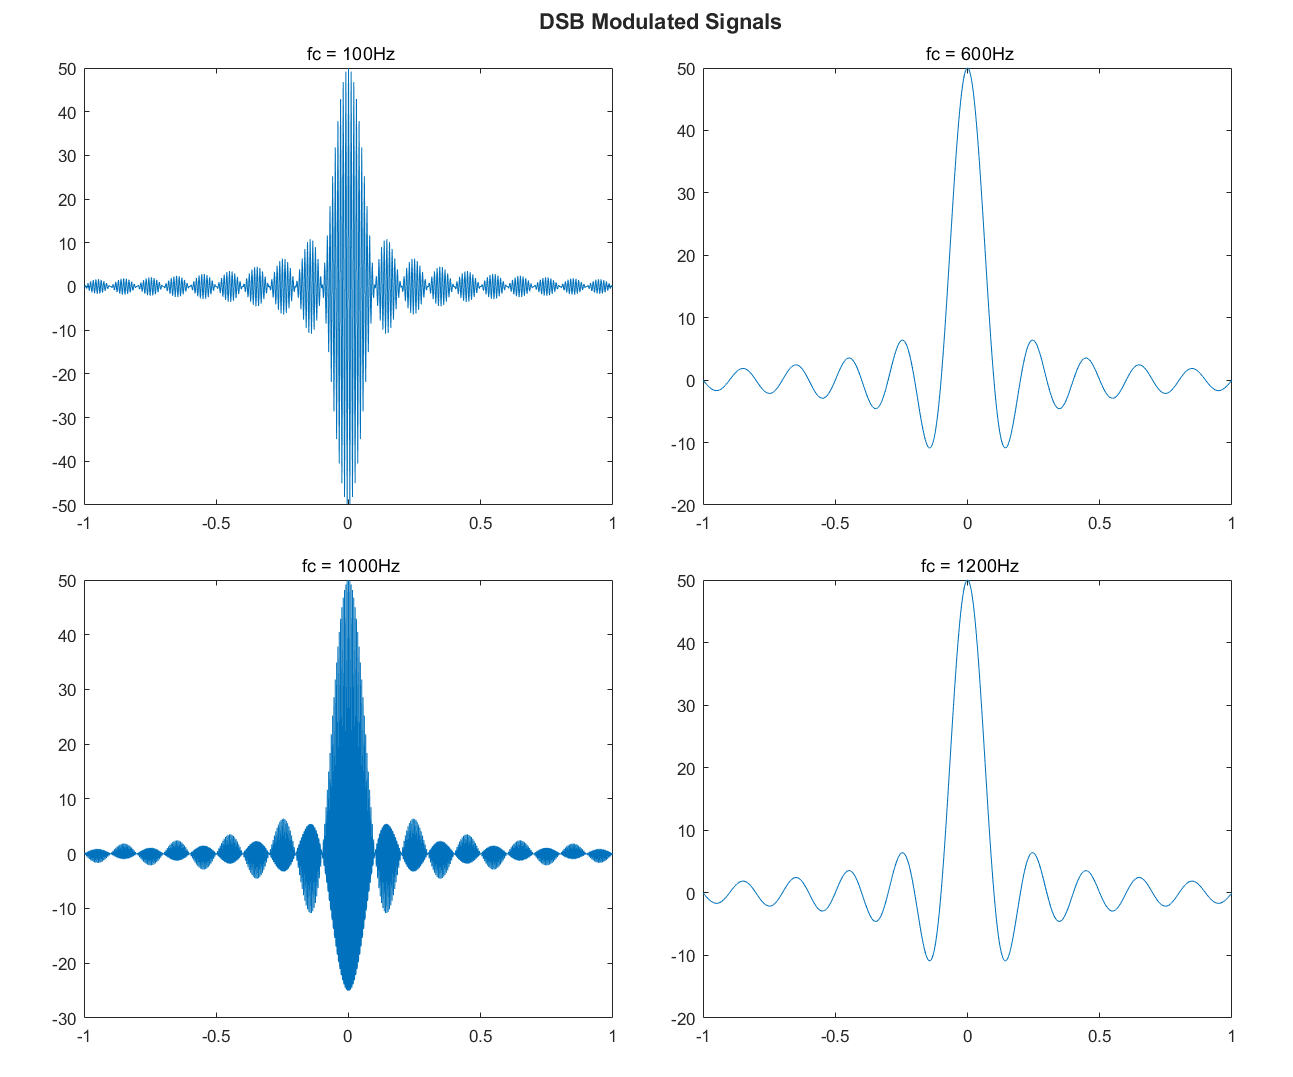

modulated_signals = cell(4, 1);

figure
fig = tiledlayout(2, 2);
fig.Padding = "compact";
fig.TileSpacing = "compact";
set(gcf, "position", [0, 0, 1200, 1000]);
for i = 1:4
    modulated_signals{i} = DSB_modulator(massage, 10, fc(i), sampling_frequency);
    nexttile
    plot(t, modulated_signals{i});
    title("\rm fc = " + string(fc(i)) + "Hz");
end
sgtitle("\bf DSB Modulated Signals");

modulated_100Hz_freqs = fftshift(fft(modulated_signals{1})) ./ length(massage);

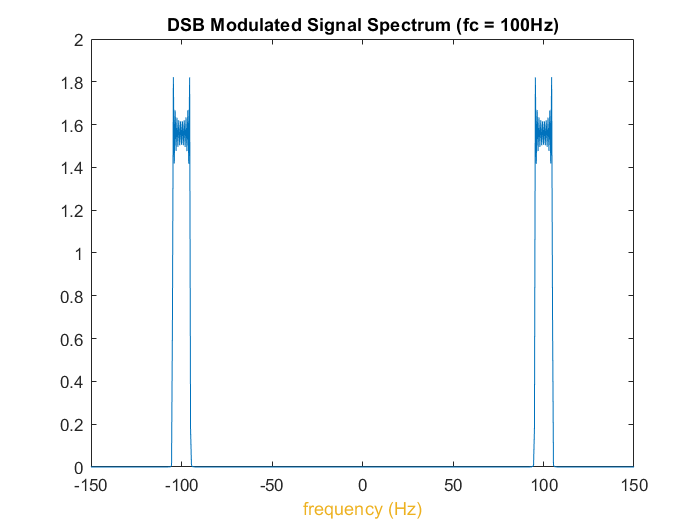

figure
plot(freqs, abs(modulated_100Hz_freqs).^2);
xlim([-150, 150]);
xlabel("frequency (Hz)", "Color", orange);
title("DSB Modulated Signal Spectrum (fc = 100Hz)");

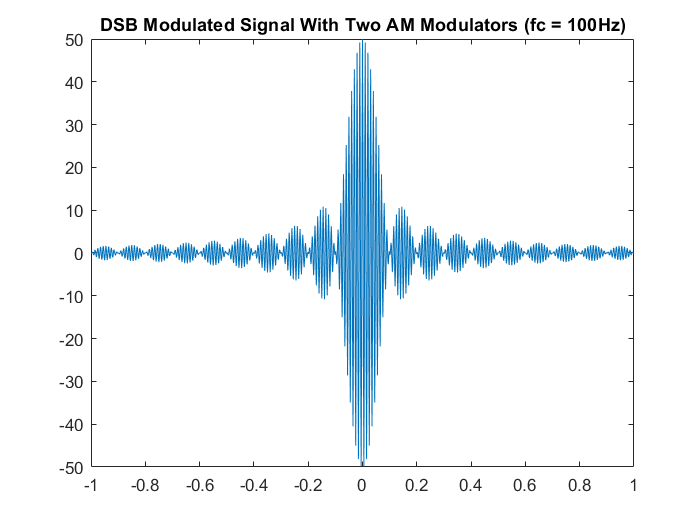

new_modulated_signal = cAM_modulator(0.5*massage, 10, 1, fc(1), sampling_frequency) - cAM_modulator(-0.5*massage, 10, 1, fc(1), sampling_frequency);

figure
plot(t, new_modulated_signal);
title("DSB Modulated Signal With Two AM Modulators (fc = 100Hz)");

fprintf("MSE = %0.5f\n", immse(modulated_signals{1}, new_modulated_signal));

MSE = 0.00000


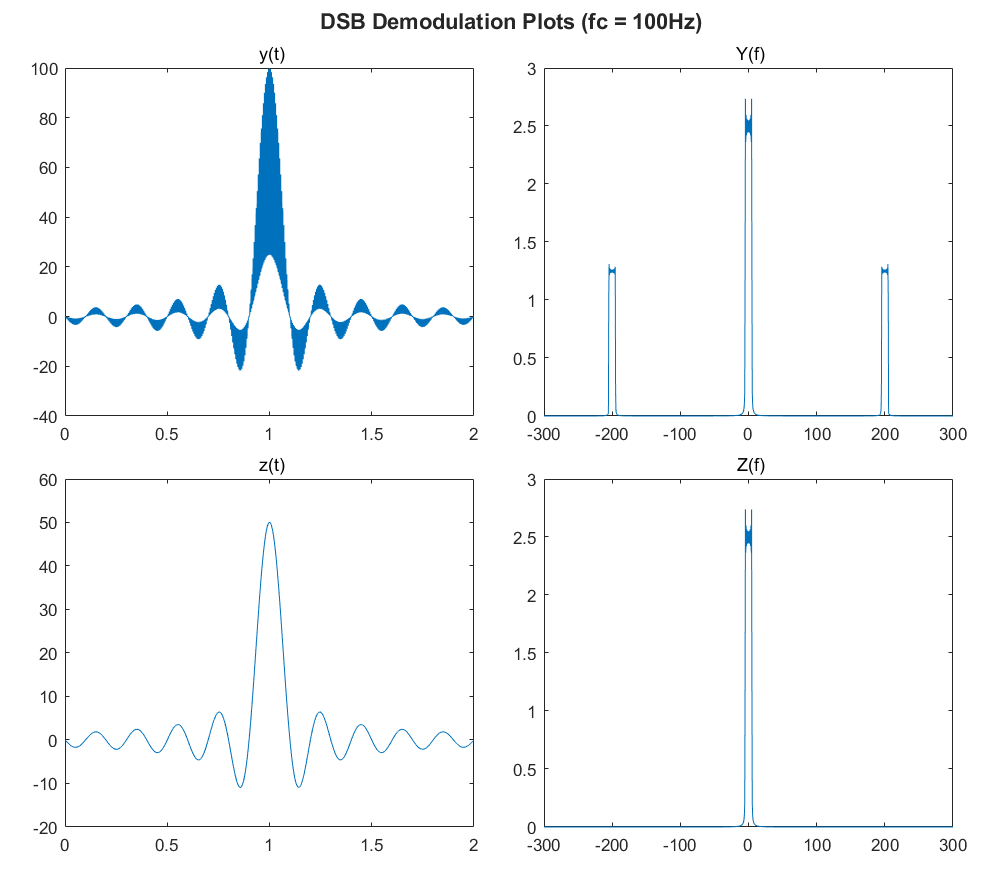

demodulated_signals{1} = DSB_demodulator_plot_steps(modulated_signals{1}, 10, fc(1), sampling_frequency);

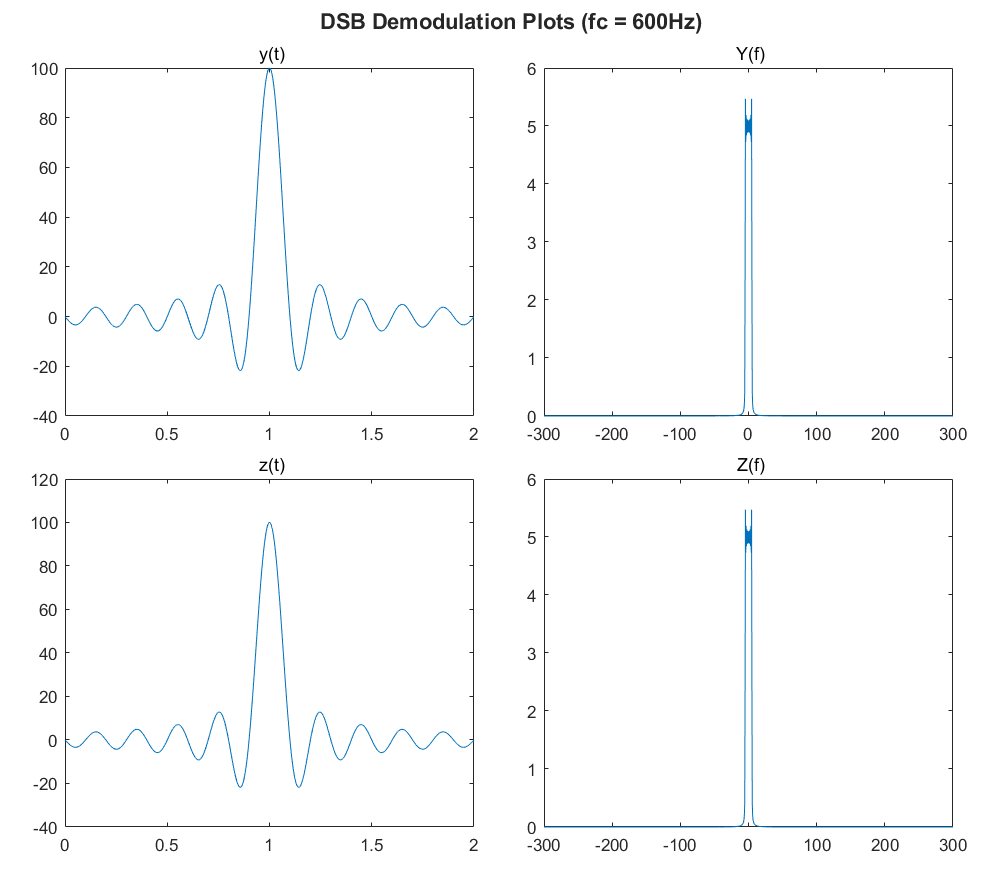

demodulated_signals{2} = DSB_demodulator_plot_steps(modulated_signals{2}, 10, fc(2), sampling_frequency);

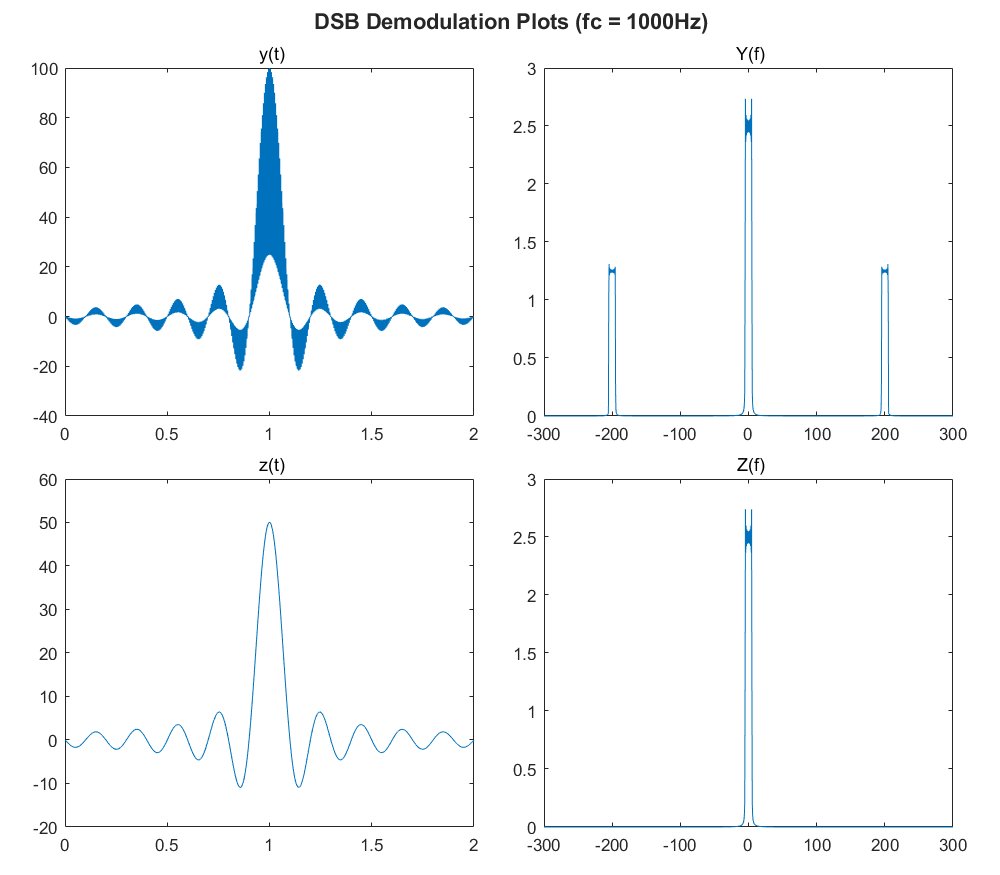

demodulated_signals{3} = DSB_demodulator_plot_steps(modulated_signals{3}, 10, fc(3), sampling_frequency);

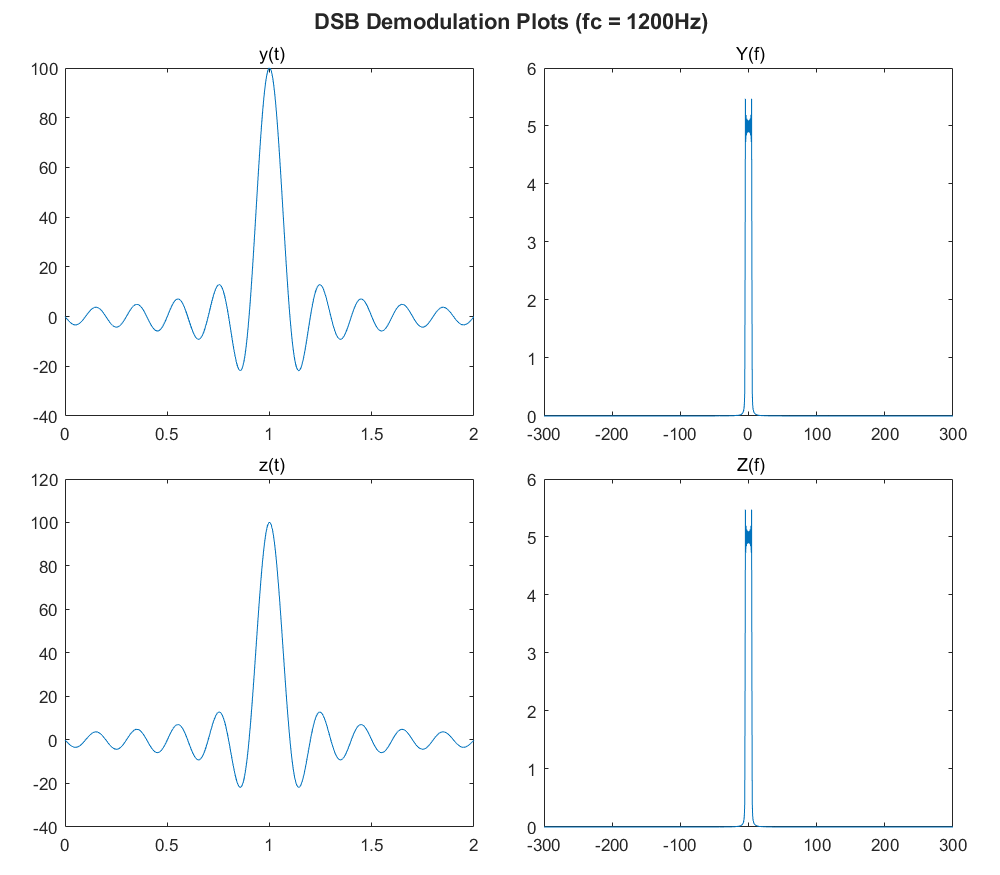

demodulated_signals{4} = DSB_demodulator_plot_steps(modulated_signals{4}, 10, fc(4), sampling_frequency);

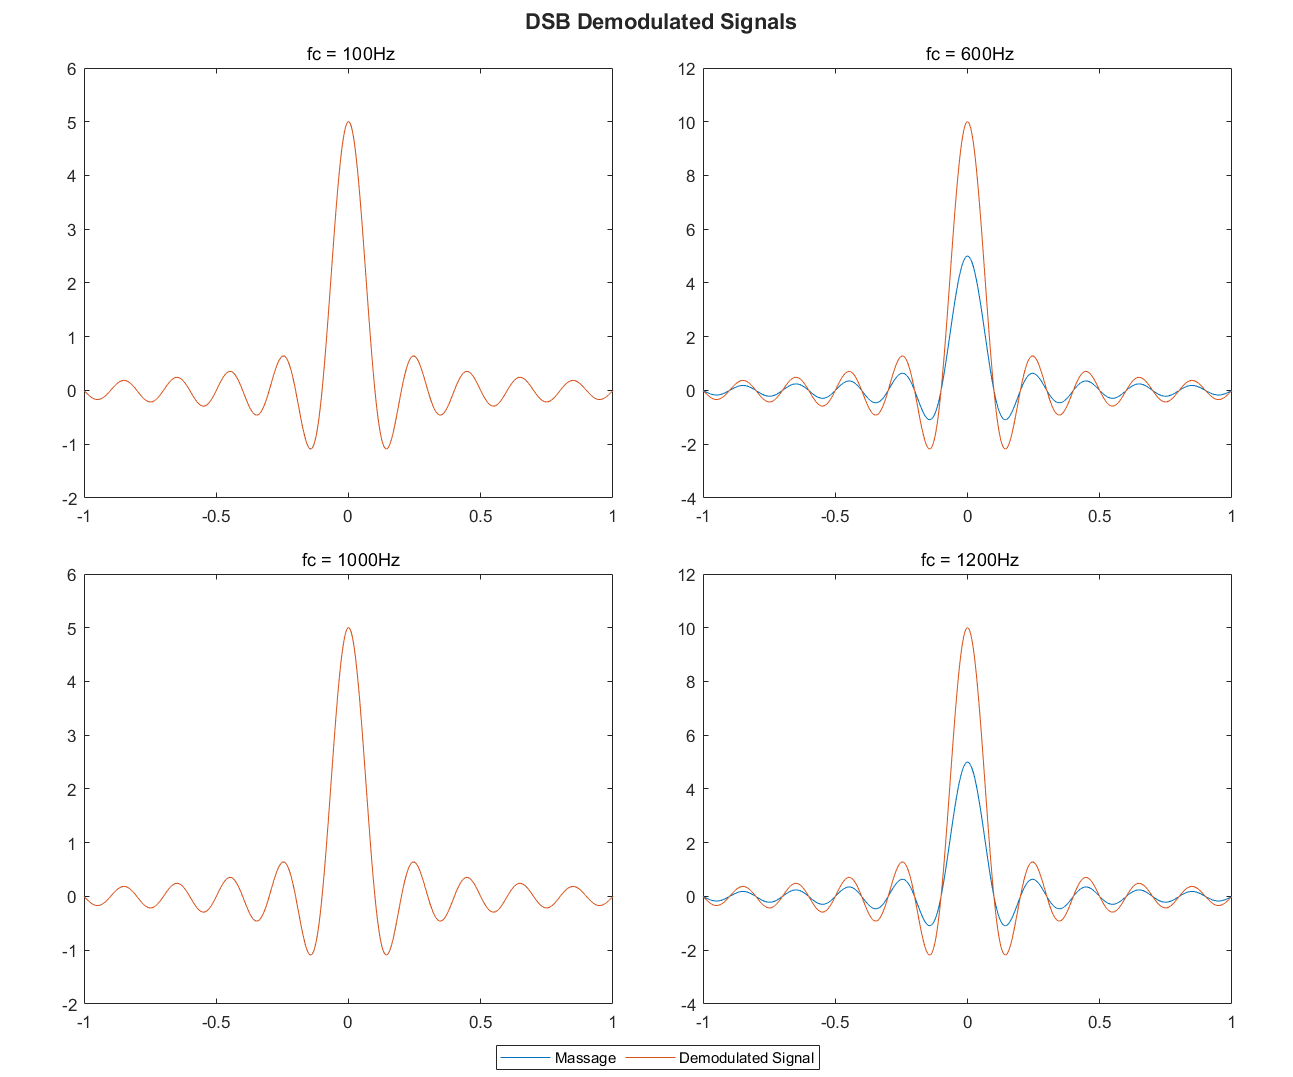

figure
fig = tiledlayout(2, 2);
fig.Padding = "compact";
fig.TileSpacing = "compact";
set(gcf, "position", [0, 0, 1200, 1000]);
for i = 1:4
    nexttile
    plot(t, massage, t, demodulated_signals{i});
    title("\rm fc = " + string(fc(i)) + "Hz");
end
sgtitle("\bf DSB Demodulated Signals");
lgnd = legend("Massage", "Demodulated Signal");
lgnd.Layout.Tile = "south";
lgnd.Orientation = "horizontal";

for i = 1:4
    fprintf("fc=%d: \t%0.5f\n", fc(i), immse(massage, demodulated_signals{i}));
end

fc=100: 	0.00000
fc=600: 	1.23796
fc=1000: 	0.00000
fc=1200: 	1.23796


tmp = zeros(501, 1);
for i = 0:500
    tmp(i+1) = immse(massage, DSB_demodulator(DSB_modulator(massage, 10, i, sampling_frequency), 10, i, sampling_frequency));
end

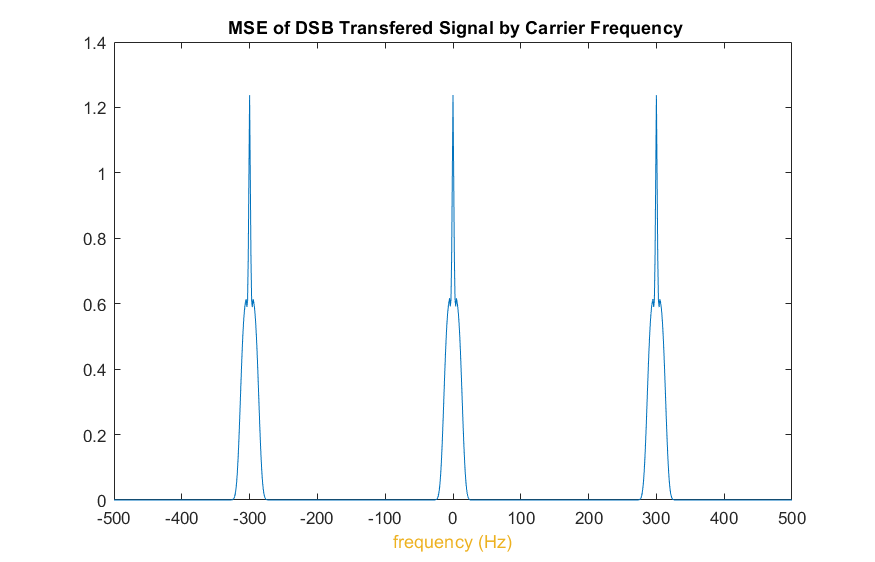

mse_errors = zeros(1001, 1);
for i = 1:501
    mse_errors(i+500) = tmp(i);
    mse_errors(502-i) = tmp(i);
end

figure
set(gcf, "position", [0, 0, 700, 450]);
plot(-500:1:500, mse_errors);
title("\bf MSE of DSB Transfered Signal by Carrier Frequency");
xlabel("frequency (Hz)", "Color", orange);

**SSB**

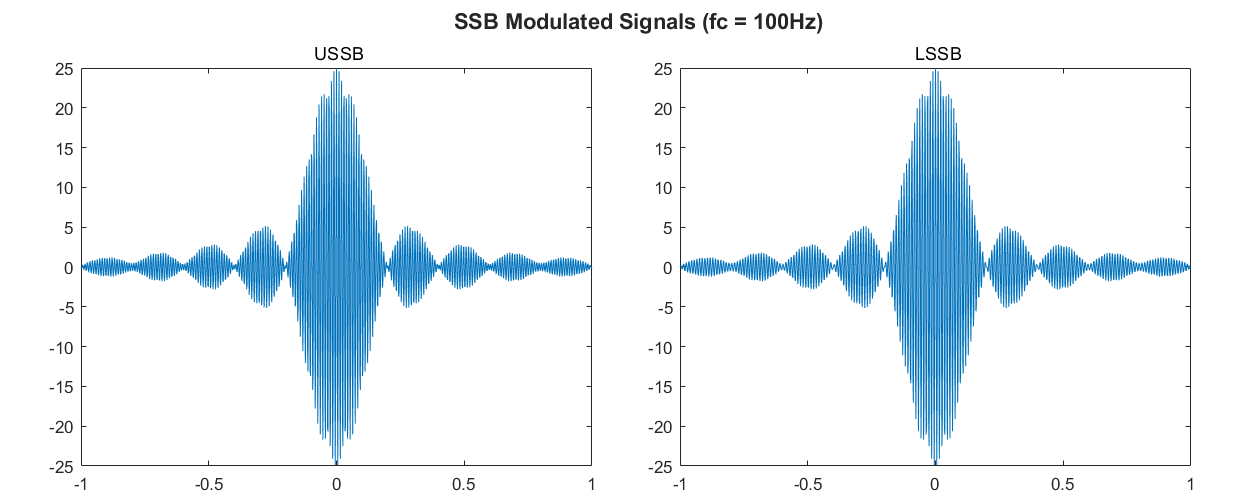

[USSB_signal, LSSB_signal] = SSB_modulator(massage, 10, 100, sampling_frequency);

figure
fig = tiledlayout(1, 2);
fig.Padding = "compact";
fig.TileSpacing = "compact";
set(gcf, "position", [0, 0, 1000, 400]);
nexttile
plot(t, USSB_signal);
title("\rm USSB");
nexttile
plot(t, LSSB_signal);
title("\rm LSSB");
sgtitle("\bf SSB Modulated Signals (fc = 100Hz)");

immse(USSB_signal, LSSB_signal)

ans = 58.8206

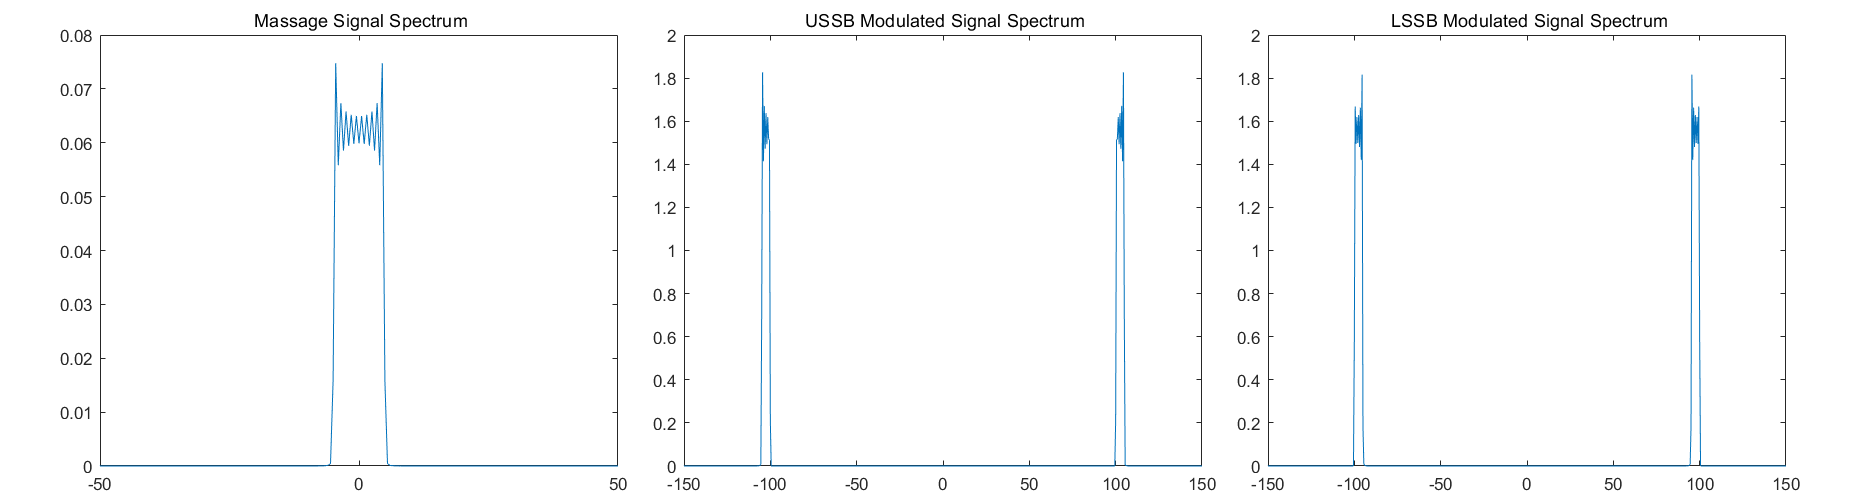

figure
fig = tiledlayout(1, 3);
fig.Padding = "compact";
fig.TileSpacing = "compact";
set(gcf, "position", [0, 0, 1500, 400]);
nexttile
plot(freqs, abs(massage_freqs) .^ 2);
xlim([-50, 50])
title("\rm Massage Signal Spectrum");
nexttile
plot(freqs, abs(fftshift(fft(USSB_signal)) / length(USSB_signal)) .^ 2);
xlim([-150, 150])
title("\rm USSB Modulated Signal Spectrum");
nexttile
plot(freqs, abs(fftshift(fft(LSSB_signal)) / length(LSSB_signal)) .^ 2);
xlim([-150, 150])
title("\rm LSSB Modulated Signal Spectrum");

function modulated_signal = cAM_modulator(massage, Ac, u, fc, sampling_frequency)
    t = 0:length(massage)-1;
    t = t/sampling_frequency;
    modulated_signal = Ac * (1 + u*massage) .* cos(2*pi*fc*t);
end

function demodulated_signal = cAM_demodulator(modulated_signal, Ac, u)
    [env, ] = envelope(modulated_signal, 10, "peak");
    demodulated_signal = (env / Ac - 1) / u;
end

function modulated_signal = DSB_modulator(massage, Ac, fc, sampling_frequency)
    t = 0:length(massage)-1;
    t = t/sampling_frequency;
    modulated_signal = Ac * massage .* cos(2*pi*fc*t);
end

function demodulated_signal = DSB_demodulator_plot_steps(modulated_signal, Ac, fc, sampling_frequency)
    
    figure
    fig = tiledlayout(2, 2);
    fig.Padding = "compact";
    fig.TileSpacing = "compact";
    set(gcf, "position", [0, 0, 800, 700]);

    t = 0 : length(modulated_signal)-1;
    t = t/sampling_frequency;
    freqs = -sampling_frequency/2 : 0.5 : sampling_frequency/2;
    demodulated_signal = 2 * cos(2*pi*fc*t) .* modulated_signal;
    fourier = abs(fftshift(fft(demodulated_signal)) ./ length(modulated_signal));

    nexttile
    plot(t, demodulated_signal);
    title("\rm y(t)");
    nexttile
    plot(freqs, fourier);
    title("\rm Y(f)");

    bw = powerbw(modulated_signal, sampling_frequency);
    demodulated_signal = lowpass(demodulated_signal, bw, sampling_frequency);

    nexttile
    plot(t, demodulated_signal)
    title("\rm z(t)");
    nexttile
    plot(freqs, abs(fftshift(fft(demodulated_signal)) ./ length(modulated_signal)));
    title("\rm Z(f)");
    sgtitle("\bf DSB Demodulation Plots (fc = " + string(fc) + "Hz)");

    demodulated_signal = demodulated_signal / Ac;
end

function demodulated_signal = DSB_demodulator(modulated_signal, Ac, fc, sampling_frequency)
    t = 0 : length(modulated_signal)-1;
    t = t/sampling_frequency;
    demodulated_signal = 2 * cos(2*pi*fc*t) .* modulated_signal;
    bw = powerbw(modulated_signal, sampling_frequency);
    demodulated_signal = lowpass(demodulated_signal, bw, sampling_frequency) / Ac;
end

function [USSB_signal, LSSB_signal] = SSB_modulator(massage, Ac, fc, sampling_frequency)
    t = 0 : length(massage)-1;
    t = t/sampling_frequency;
    tmp = imag(hilbert(massage)) .* sin(2*pi*fc*t);
    USSB_signal = massage .* cos(2*pi*fc*t);
    LSSB_signal = (USSB_signal + tmp) * Ac * 0.5;
    USSB_signal = (USSB_signal - tmp) * Ac * 0.5;
end